# Signal Frequency Analysis

how can we determine what is the frequency content of a signal? So far, we have just visualize the waveforms and inspected whether there were lots of oscillations. However, we have tools that let us quantify the power of 

different frequencies contained in a signal. The main tool for this frequency analysis is called the Fourier transform, 

named after French mathematician Fourier. Specifically for discrete time signals such as those we represent in MATLAB. This is the discrete Fourier transform. This is implemented in MATLAB as the function FFT, 

which stands for the fast Fourier transform. This function efficiently converts a time-domain signal, 

that is a signal that varies over time, into a frequency domain signal, that is a signal that is 

represented not by how it changes over time, but by how much different frequencies contribute to the signal. This will not only let us easily see or quantify what frequencies exist in the signal, we can also very easily manipulate the frequency content of a signal in the frequency domain and then return the manipulated signal to the time domain form using the inverse Fourier transform, which is implemented as IFFT in MATLAB. 

Let's go to MATLAB and see how this works.

Fs = 13200;
f1 = 440;
f2 = 660;
T = 5;
t = [0:1/Fs:T-1/Fs]';
y1 = cos(2*pi*f1*t);
y2 = cos(2*pi*f2*t + pi/4);%phase shifted
y = y1 + y2;

## Plot the signals

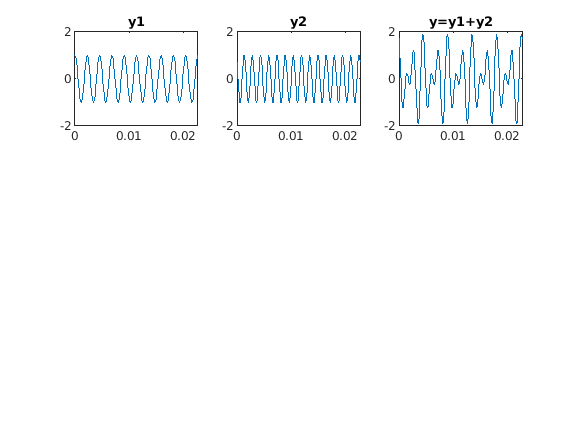

figure(1);
subplot(3,3,1);
plot(t,y1);title("y1");
axis([0,5/220,-2,2]);
subplot(3,3,2);
plot(t,y2);title("y2");
axis([0,5/220,-2,2]);
subplot(3,3,3);
plot(t,y);title("y=y1+y2");
axis([0,5/220,-2,2]);

## Compute FFT

we can note that the period of a signal that is a combination of two periodic signals is one divided by the largest common denominator of the frequencies of the two individual pure tone signals

yfft = fft(y);
yfft(1:10)

ans = 	1.0e+-9 *

  -0.3279 + 0.0000i
  -0.2400 - 0.1688i
  -0.0968 - 0.2399i
   0.0214 - 0.1351i
   0.0650 - 0.0395i
  -0.0226 - 0.0116i
  -0.0271 - 0.0200i
  -0.0379 - 0.0824i
  -0.0018 - 0.0435i
   0.0363 - 0.0160i


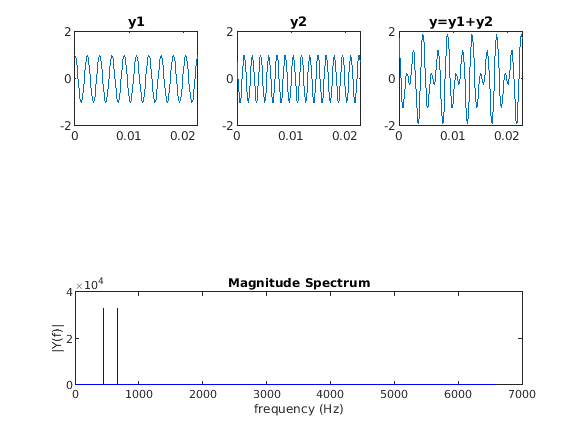

[yfft, f]=myfft(y,Fs);
subplot(3,1,3);
MagnitudeSpectrumPlot(yfft,f);

yfft(f==440);
length(y)/2;

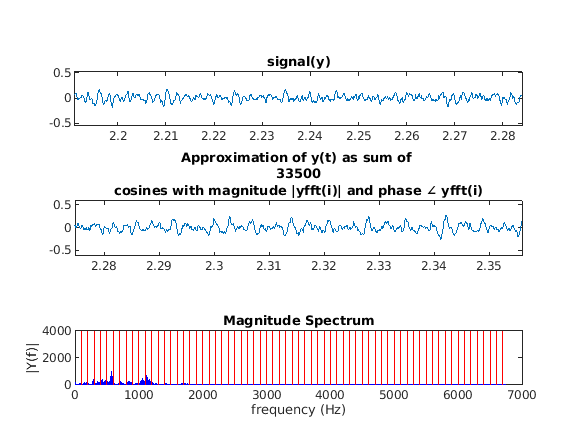

[y Fs] = audioread("handel_audio.wav");
FsResamp = 13500;
t = [0:1/FsResamp:5];
yresamp = interp1([0:1/Fs:(length(y)-1)/Fs],y,t);
subplot(3,1,1);plot(t,yresamp);title('signal(y)');axis([0,5,-1,1]);
[yfft f] = myfft(yresamp, FsResamp);
subplot(3,1,3);
MagnitudeSpectrumPlot(yfft,f);
ycos = zeros(size(yresamp));
for i=1:length(yfft)
    if i==1 || (i==length(yfft) && f(end)==FsResamp/2)
        ycos = ycos + abs(yfft(i))/length(yresamp) * cos(2*pi*f(i)*t + angle(yfft(i)));
    else
        ycos = ycos + abs(yfft(i))/(length(yresamp)/2) * cos(2*pi*f(i)*t + angle(yfft(i)));
    end
    if mod(i,500)==0
        %update plot every 100
        subplot(3,1,2);
        plot(t,ycos);
        axis([0,5,-1,1]);
        title(["Approximation of y(t) as sum of ",num2str(i),"cosines with magnitude |yfft(i)| and phase \angle yfft(i)"]);
        drawnow;
        subplot(3,1,3);
        hold on;
        plot([f(i), f(i)], [0, 4000],'r');
    end
end

## Verify y is equal to ycos using the following

sum((yresamp-ycos).^2)

ans = 8.6073e-21

## Highpass Filter

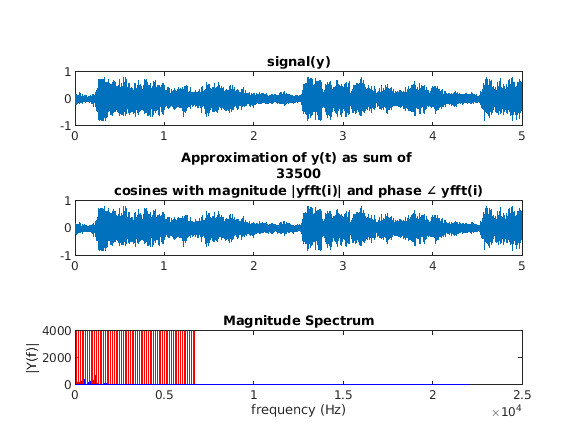

H = f>1500;
yfftfilt = yfft.*H;
MagnitudeSpectrumPlot(yfftfilt,f);